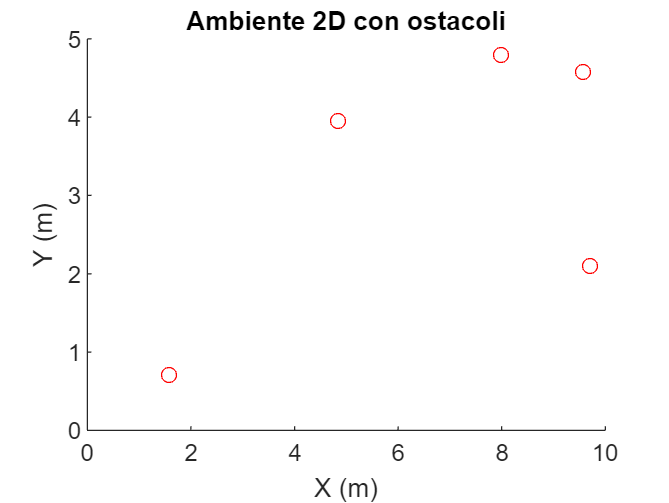

% Definizione delle dimensioni dell'ambiente
lunghezza_ambiente = 10; % lunghezza in metri
larghezza_ambiente = 5; % larghezza in metri

% Generazione casuale di ostacoli nell'ambiente
numero_ostacoli = 5;
ostacoli_x = rand(1, numero_ostacoli) * lunghezza_ambiente;
ostacoli_y = rand(1, numero_ostacoli) * larghezza_ambiente;

% Disegna l'ambiente e gli ostacoli
figure;
hold on;
plot(ostacoli_x, ostacoli_y, 'ro'); % Disegna gli ostacoli come cerchi rossi
xlim([0, lunghezza_ambiente]);
ylim([0, larghezza_ambiente]);
xlabel('X (m)');
ylabel('Y (m)');
title('Ambiente 2D con ostacoli');

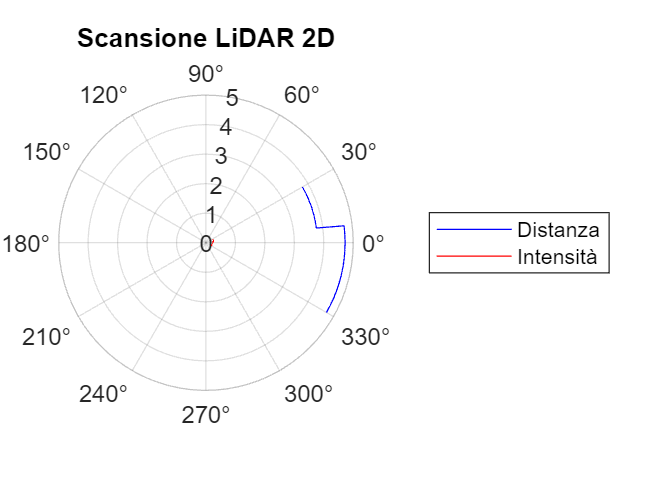


% Posizione del LiDAR
posizione_lidar_x = lunghezza_ambiente / 2; % Centrato lungo l'asse x
posizione_lidar_y = larghezza_ambiente / 2; % Centrato lungo l'asse y

% Parametri del LiDAR 2D
angolo_apertura = 60; % Gradi
massima_distanza = 5; % Metri

% Simulazione della scansione LiDAR 2D
angolo_iniziale = -angolo_apertura / 2;
angolo_finale = angolo_apertura / 2;
numero_scansioni = 100;
angoli_scansioni = linspace(angolo_iniziale, angolo_finale, numero_scansioni);

% Inizializza matrici per salvare i dati della scansione LiDAR
distanze = zeros(size(angoli_scansioni));
intensita = zeros(size(angoli_scansioni));

% Scansiona l'ambiente con il LiDAR
for i = 1:length(angoli_scansioni)
    angolo = angoli_scansioni(i);
    direzione_x = cosd(angolo);
    direzione_y = sind(angolo);
    
    % Trova ostacoli lungo la direzione della scansione
    [distanza, indice_ostacolo] = trova_ostacolo(posizione_lidar_x, posizione_lidar_y, direzione_x, direzione_y, ostacoli_x, ostacoli_y);
    
    % Salva la distanza e l'intensità del segnale LiDAR
    if ~isempty(indice_ostacolo)
        distanze(i) = distanza;
        intensita(i) = 1 / distanza; % Intensità inversamente proporzionale alla distanza
    else
        distanze(i) = massima_distanza;
        intensita(i) = 0; % Nessun ritorno del segnale
    end
end

% Plot della scansione LiDAR
figure;
polarplot(deg2rad(angoli_scansioni), distanze, 'b'); % Distanza
hold on;
polarplot(deg2rad(angoli_scansioni), intensita, 'r'); % Intensità
title('Scansione LiDAR 2D');
legend('Distanza', 'Intensità');